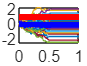

n = 1000;m=100;
[w,t] = wiener(n,m);
I = 2*kvar(w); %kvadratikus variáció a folyamat változékonyságát méri 
a=1;
for i=1:m
    tau = find(I(:,i)>a,1);
    w(tau:end,i) = w(tau,i);
end
plot(t,w);
hold on
plot(t,ones(size(t))*a,"r","LineWidth",3);
plot(t,zeros(size(t)),"g","LineWidth",3);
plot(t,mean(w,2),"b","LineWidth",3);
hold off